if ~exist('a4', 'var')
    parametry_robota;
end

=== OBLICZONE PARAMETRY ===
M_tot = 1.7500
J_tot = 0.0325
Det (a4) = 0.0344
a2 = -2.5751
b2 = -5.5000


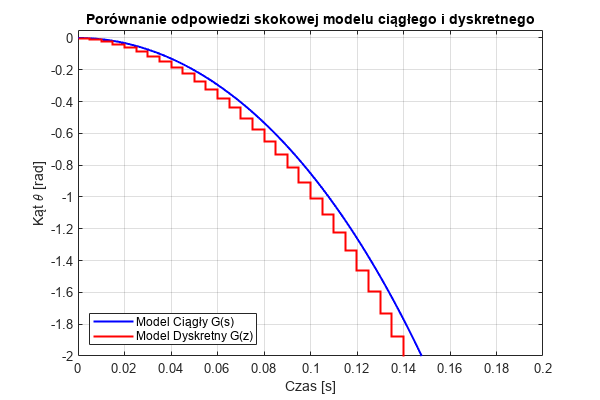


Licznik_s = [b2];
Mianownik_s = [a4, 0, a2];

Gs = tf(Licznik_s, Mianownik_s);
Gs.InputName = 'u';
Gs.OutputName = 'theta';

% G_d(z) = (Q0 * z^2) / (W * z^2 - P1 * z - P2)
W  = a4 + a2 * Ts^2;
P1 = 2 * a4;
P2 = -a4;
Q0 = b2 * Ts^2;

Licznik_z = [Q0, 0, 0];
Mianownik_z = [W, -P1, -P2];

Gz_euler = tf(Licznik_z, Mianownik_z, Ts);

Gz_tustin = c2d(Gs, Ts, 'tustin'); 

figure(1);

T_plot = 0.2;

[y_c, t_c] = step(Gs, T_plot);

[y_d, t_d] = step(Gz_euler, T_plot);

set(gcf, 'Position', [100, 100, 600, 400]);
plot(t_c, y_c, 'b', 'LineWidth', 1.5); 
hold on;

stairs(t_d, y_d, 'r', 'LineWidth', 1.5);
title('Porównanie odpowiedzi skokowej modelu ciągłego i dyskretnego');
xlabel('Czas [s]');
ylabel('Kąt \theta [rad]');
legend('Model Ciągły G(s)', 'Model Dyskretny G(z)', 'Location', 'SouthWest');
xlim([0, 0.2]);
ylim([-2, 0.05]);
grid on;
hold off;
print('Odp_skok_G.png', '-dpng', '-r400');

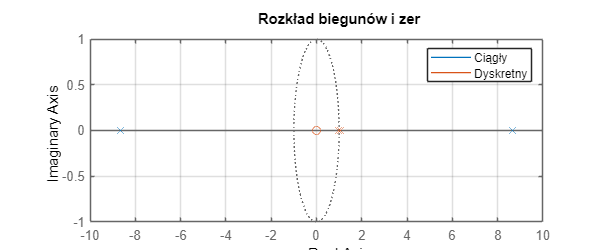


figure('Position', [100, 100, 600, 250]);
pzmap(Gs, Gz_euler);
title('Rozkład biegunów i zer');
legend('Ciągły', 'Dyskretny');
grid on;
print('RozkladBieg_G.png', '-dpng', '-r400');


disp('--- Transmitancja Ciągła G(s) ---');

--- Transmitancja Ciągła G(s) ---


Gs

Gs =
 
  From input "u" to output "theta":
         -5.5
  -------------------
  0.03438 s^2 - 2.575
 
Continuous-time transfer function.



disp('--- Transmitancja Dyskretna G(z) [Twoja metoda Eulera] ---');

--- Transmitancja Dyskretna G(z) [Twoja metoda Eulera] ---


Gz_euler

Gz_euler =
 
           -0.0001375 z^2
  ---------------------------------
  0.03431 z^2 - 0.06875 z + 0.03438
 
Sample time: 0.005 seconds
Discrete-time transfer function.

